Problem 1

x = [1, 2, 3, 4, 5, 6, 7, 8]

x =      1     2     3     4     5     6     7     8


x_fft = fft(x)

x_fft =   36.0000 + 0.0000i  -4.0000 + 9.6569i  -4.0000 + 4.0000i  -4.0000 + 1.6569i  -4.0000 + 0.0000i  -4.0000 - 1.6569i  -4.0000 - 4.0000i  -4.0000 - 9.6569i


x_ifft = ifft(x_fft)

x_ifft =      1     2     3     4     5     6     7     8



x_myfft = myFFT(x)

x_myfft =   36.0000 + 0.0000i  -4.0000 + 9.6569i  -4.0000 + 4.0000i  -4.0000 + 1.6569i  -4.0000 - 0.0000i  -4.0000 - 1.6569i  -4.0000 - 4.0000i  -4.0000 - 9.6569i


x_myifft = myIFFT(x_myfft)

x_myifft =    1.0000 - 0.0000i   2.0000 - 0.0000i   3.0000 - 0.0000i   4.0000 - 0.0000i   5.0000 - 0.0000i   6.0000 + 0.0000i   7.0000 + 0.0000i   8.0000 + 0.0000i


Problem 2

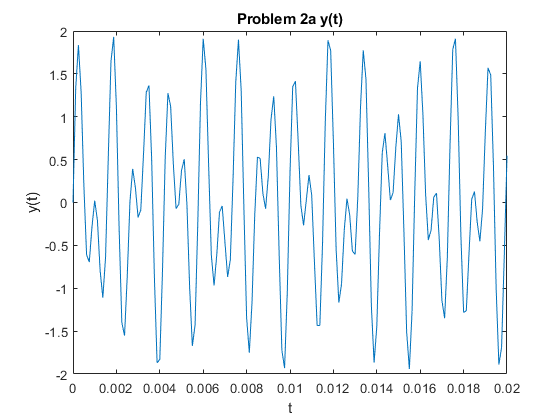

fs = 8000; % sample rate in Hz
dt = 1/fs; % sampling interval
t = 0:dt:1;

f1 = 697; % Hz
f2  = 1209; % Hz

y = sin(2*pi*f1*t) + sin(2*pi*f2*t);
plot(t, y)
axis([0 0.02 -2 2])
title('Problem 2a y(t)');
xlabel('t');
ylabel('y(t)');

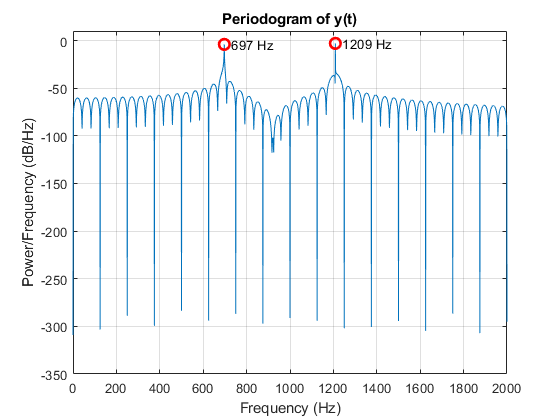


[pxx, f] = periodogram(y, [], [], fs);
pxx_db = 10*log10(pxx);

plot(f, pxx_db)
title('Periodogram of y(t)')
xlabel('Frequency (Hz)');
ylabel('Power/Frequency (dB/Hz)');
xlim([0 2000]);
ylim([-350 10])
grid on
hold on

[~, i1] = min(abs(f - 697));
[~, i2] = min(abs(f - 1209));
plot(f(i1), pxx_db(i1), 'ro', 'MarkerSize', 8, 'LineWidth', 2)
plot(f(i2), pxx_db(i2), 'ro', 'MarkerSize', 8, 'LineWidth', 2)
text(f(i1), pxx_db(i1), '  697 Hz')
text(f(i2), pxx_db(i2), '  1209 Hz')
hold off

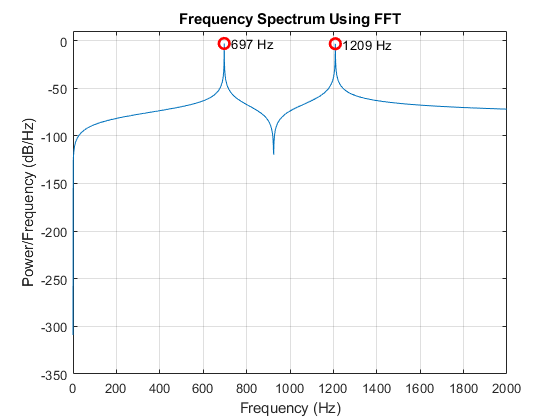


% signalAnalyzer(y) 
% screenshot of signal analyzer at the bottom of the pdf

N = length(y);
Y = fft(y);

P2 = abs(Y/N).^2;
P1 = P2(1:floor(N/2)+1);
P1(2:end-1) = 2*P1(2:end-1);
P1_dB = 10*log10(P1);
f = fs*(0:floor(N/2))/N;

plot(f, P1_dB)
xlabel('Frequency (Hz)')
ylabel('Power/Frequency (dB/Hz)')
title('Frequency Spectrum Using FFT')
axis([0 2000 -350 10])
grid on
hold on

[~, i1] = min(abs(f - f1));
[~, i2] = min(abs(f - f2));
plot(f(i1), P1_dB(i1), 'ro', 'MarkerSize', 8, 'LineWidth', 2)
plot(f(i2), P1_dB(i2), 'ro', 'MarkerSize', 8, 'LineWidth', 2)
text(f(i1), P1_dB(i1), '  697 Hz')
text(f(i2), P1_dB(i2), '  1209 Hz')

hold off

Problem 1 Defined FFT and IFFT Functions

function X = myFFT(x) 
    N = length(x);
    W = exp(-1j*(2*pi/N));
    
    X = zeros(1,N);
    
    for k = 0:N-1
       for n = 0:N-1
          X(k+1) = X(k+1) + x(n+1)*W^(k*n); 
       end
    end
end

function x = myIFFT(X)
    N = length(X);
    W = exp(-1j*(2*pi/N));
    
    x = zeros(1,N);
    
    for k = 0:N-1
       for n = 0:N-1
          x(n+1) = x(n+1) + X(k+1)*W^(-1*k*n); 
       end
    end
    
    x = x/N;
end